# Image and Video Processing - Task 1

## Prewitt Edge Detector and Nonmaxima Suppression

Daniel Kuknyo - [Y80L35]

### Read and setup

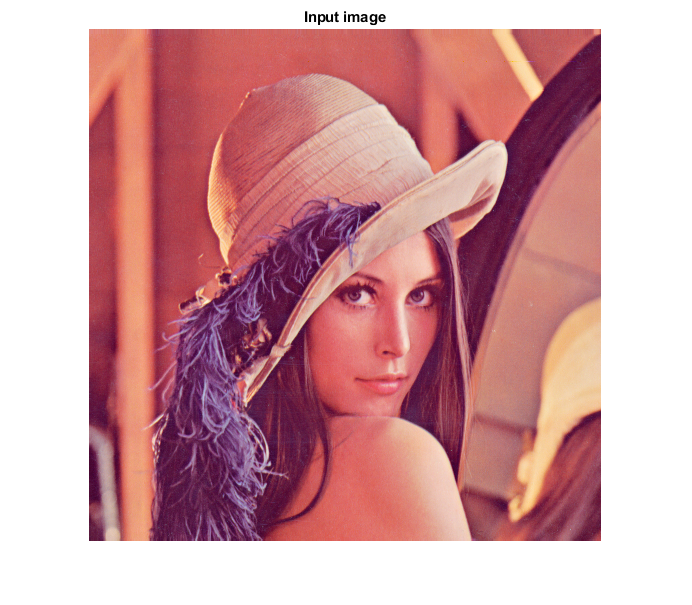

clear all; clc;

% Parameters
imname = 'Lenna.png';

img = uint8(imread(imname));
figure;
imshow(img);
title('Input image');

### Setting up

% Prewitt filter mask
xmask = [-1  0  1; 
         -1  0  1; 
         -1  0  1];

ymask = [-1 -1 -1; 
          0  0  0; 
          1  1  1];

% Converting the image
img = double(rgb2gray(img));
gradients = zeros(size(img));

% Window size
kernel_size = 2;

### Running the filter

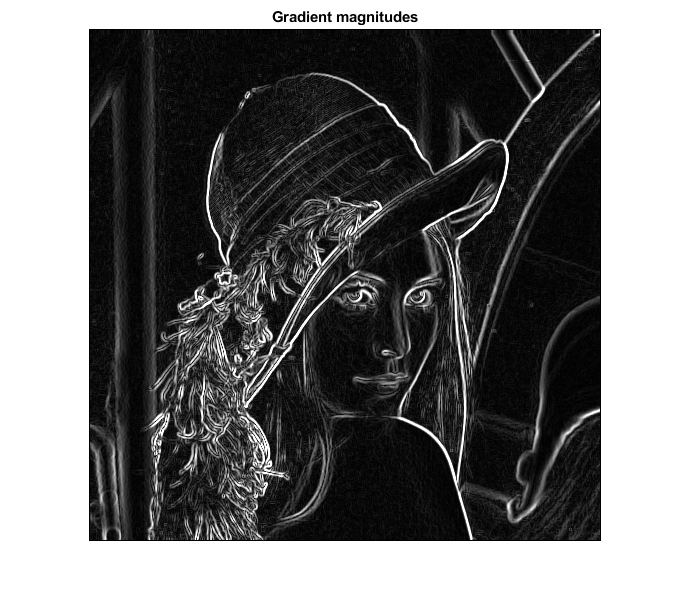

for i = 1:size(img, 1) - kernel_size
    for j = 1:size(img, 2) - kernel_size
        % Calculating the gradients
        Gx = sum(sum(xmask.*img(i:i+kernel_size, j:j+kernel_size)));
        Gy = sum(sum(ymask.*img(i:i+kernel_size, j:j+kernel_size)));
                 
        gradients(i+1, j+1) = sqrt(Gx.^2 + Gy.^2); % Gradient norms
    end
end
  
% Displaying Filtered Image
gradients = uint8(gradients);
figure; 
imshow(gradients); 
title('Gradient magnitudes');

### Nonmaxima suppression

% Matrices to compare values from the main direction
imat = [-2 -2 -2  0  0  2  0  2;
        -2  0  2 -2  2 -2  2  2];

jmat = [-1 -1 -1  0  0  1  0  1;
        -1  0  1 -1  1 -1  1  1];


for i = 3:size(gradients, 1) - 2
    for j = 3:size(gradients, 2) - 2
        m_c = gradients(i, j);
        for k = 1:8
            coord1_x = imat(1, k);
            coord1_y = imat(2, k);
            coord2_x = jmat(1, k);
            coord2_y = jmat(2, k);

            m_a = gradients(i-coord1_x, j-coord1_y);
            m_b = gradients(i-coord2_x, j-coord2_y);

            if(m_a > m_c || m_b > m_c)
                gradients(i, j) = 0;
            end
        end
    end
end    

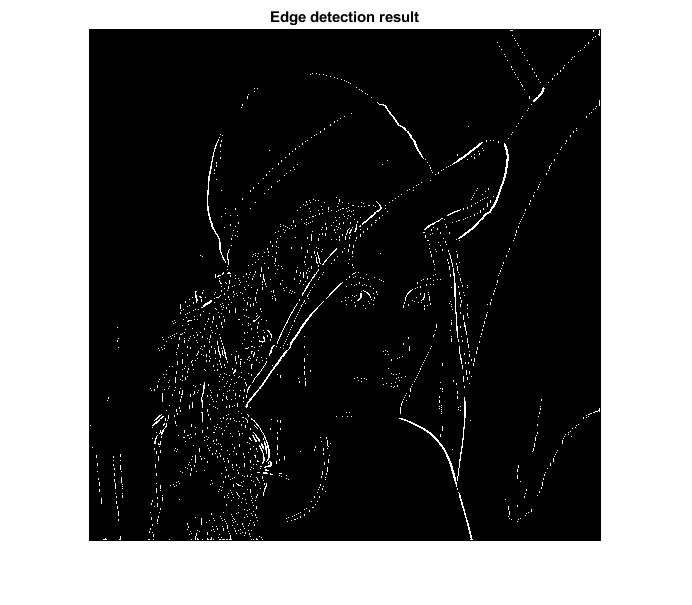

% Displaying Output Image
result = imbinarize(gradients);

fig = figure; 
imshow(result); 
title('Edge detection result');
saveas(fig, strcat('Prewitt_', imname));